**Optimization**

%fminsearch(fun,x0)
fHandle=@(x) cos(x);
x0=3;
xmin=fminsearch(fHandle,x0)

xmin = 3.1416

fHandle(xmin)

ans = -1.0000

%use function handle
%fHandle=@(arg1,...) FunctionDefinition

**Curve fitting**

%lsqcurvefit(fun,x0,xdata,ydata)

**solving ODEs**

%[tSol,ySol]ode45(derivFunction,interval,initialValue)

Three inputs for the function:

1.Function:y'=f(t,y)

%function_handle

2.interval of independent variable

%tSpan=[tStart,tEnd]

3.initial valuey(t_start)=y0

%y(tStart)=y0

tSol=[tStart;...;tEnd];

ySol=[yStart;...;yEnd];

Eg: Logistic Growth Model--P_dot=rP(1-P/K)

r=1;
K=1000;
odefun=@(t,P) r*P*(1-P/K);
tSpan=[0,10];
P0=20;
[tSol,PSol]=ode113(odefun,tSpan,P0)

tSol =          0
    0.0081
    0.0242
    0.0565
    0.1210
    0.2501
    0.5082
    0.7664
    1.2827
    1.7989


PSol =    20.0000
   20.1587
   20.4799
   21.1373
   22.5147
   25.5374
   32.8116
   42.0688
   68.5514
  109.7976


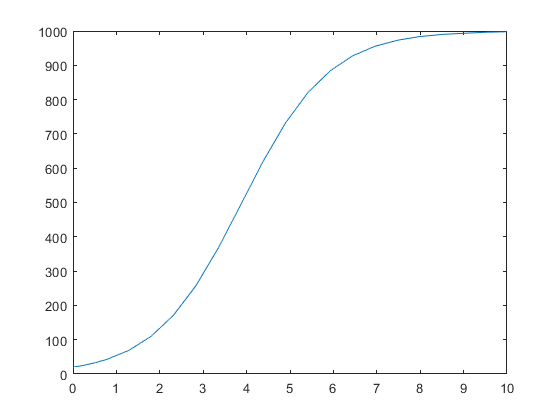

plot(tSol,PSol);

**Solve Higher Order ODEs**

 1.transform higher order ODEs--->first order system of ODEs--->first order vector-valued ODE--->ode45

Eg:d^2x/dt^2=-dx/dt-x

we use new variables: x1=x, x2=dx/dt

then we have new derivatives: dx1/dt=dx/dt; dx2/dt=d^2x/dt^2 

dxdt=@(t,x) [x(2); -x(2)-x(1)];
tLim=[0,10];
x0=[0,1];
[tSol,xSol]=ode45(dxdt,tLim,x0);
x=xSol(:,1);
max(x)

ans = 0.5455

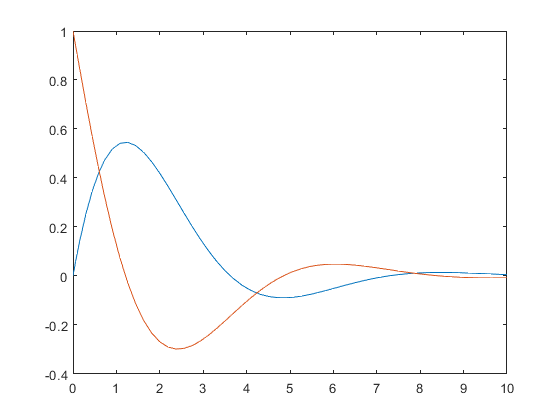

plot(tSol,xSol)